# DDMR Kinematics

[https://www.semanticscholar.org/paper/Controllers-design-for-differential-drive-mobile-on-Contreras-Herrera/02e4ee7a2c7df20833e24977e4fb2eb052186726](https://www.semanticscholar.org/paper/Controllers-design-for-differential-drive-mobile-on-Contreras-Herrera/02e4ee7a2c7df20833e24977e4fb2eb052186726)

[https://www.youtube.com/watch?v=YxuJFQZh94Q](https://www.youtube.com/watch?v=YxuJFQZh94Q)

[https://www.youtube.com/watch?v=RZlZcDxQ8P4](https://www.youtube.com/watch?v=RZlZcDxQ8P4) 

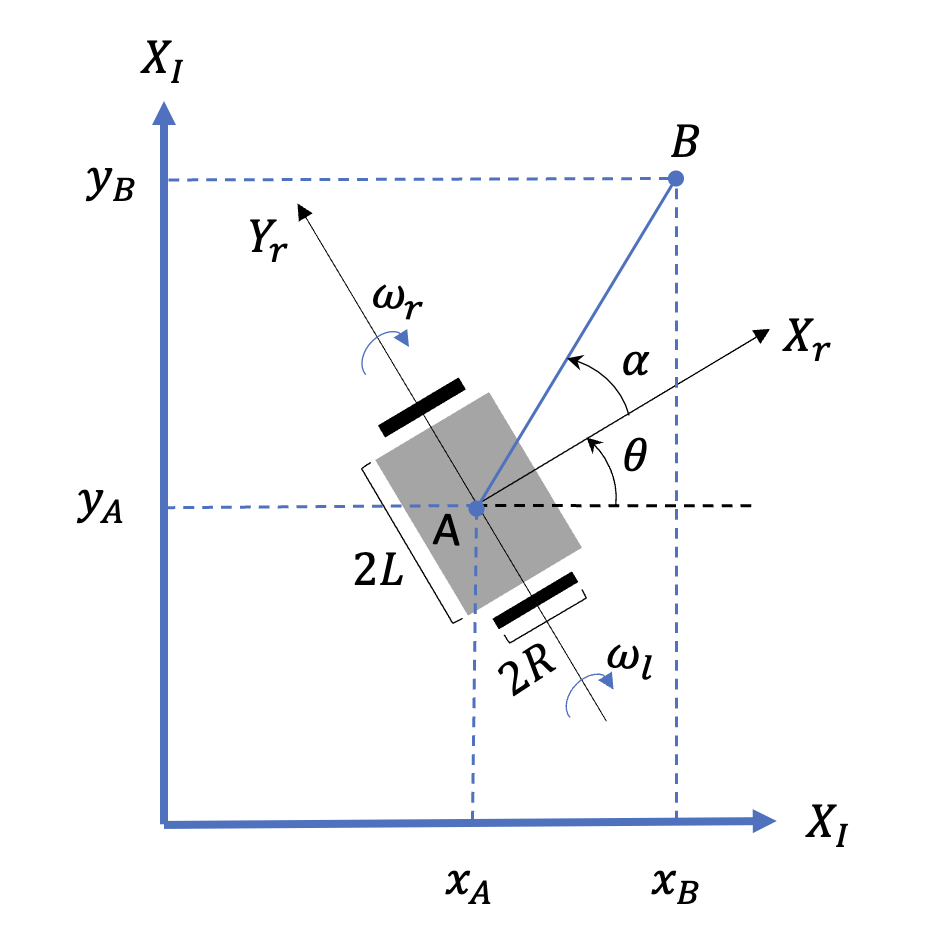

% Model Parameters
L = 10;     % Wheel Base 
R = 0.035;    % Wheel Radius m
theta = pi/4;  % Robot Heading

$\left\lbrace X_{I\;} ,Y_I \right\rbrace$ Inerial Frame

$\left\lbrace X_r \;,Y_r \right\rbrace$ Inerial Frame

$\omega_r \left(t\right)$ Right Wheel angular speed             [rad/s]

$\omega_l \left(t\right)$ Left Wheel angualr speed                [rad/s]

$v_A \left(t\right)$ Body linear velocity                          [m/s]

$\omega_A \left(t\right)$ Body angular velocity                      [rad/s]

$\theta$ Robot heading angle                             [rad]

$x_A$ Body x position in Interial Frame 

$y_A$ Body y position in Intertial Frame

### Forward Kinematics 


$${\dot{q} }_A =\left\lbrack \begin{array}{c}
{\dot{x} }_A \\
{\dot{y} }_A \\
{\dot{\theta} }_A 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{\textrm{Rcos}\left(\theta \right)}{2} & \frac{\textrm{Rcos}\left(\theta \right)}{2}\\
\frac{\textrm{Rsin}\left(\theta \right)}{2} & \frac{\textrm{Rsin}\left(\theta \right)}{2}\\
\frac{2R}{L} & -\frac{2R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\omega_r \\
\omega_l 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & 0\\
\sin \left(\theta \right) & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_a \\
\omega_a 
\end{array}\right\rbrack$$
 


$$v_A =R\;\frac{\omega_r +\omega_l }{2}$$



$$\omega_A =R\;\frac{\omega_r -\omega_l }{2L}$$


$\omega_r$ = $v_A -\omega_A L$

$\omega_l$ = $v_A +\omega_A L$

wR = 10; %rad/s
wL = 5; % rad/s
q_dot = [(R*cos(theta)/2) (R*cos(theta)) ; (R*sin(theta)/2) (R*sin(theta)/2); (2*R/L) ((-2*R)/L) ] * [wR ;wL]

#### Error Model

A Target pose, termed the reference posre $q_r \left(t\right)$, in local coordinate system is used to model the error in the Kinematics Model


$$q_r \left(t\right)=\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & \sin \left(\theta \right) & 0\\
-\sin \left(\theta \right) & \cos \left(\theta \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_{A,\;c} -x_{A,\;r} \\
y_{A,\;c\;} -y_{A,\;r} 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
{\dot{e} }_1 \left(t\right)\\
{\dot{e} }_2 \left(t\right)\\
{\dot{e} }_3 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(e_3 \left(t\right)\right) & \\
\sin \left(e_3 \left(t\right)\right) & \\
 & 
\end{array}\right\rbrack$$
